Jakub Mazur grupa wt. godz 14:15 a

Przykład 1. Złe przedstawienie wykresu.

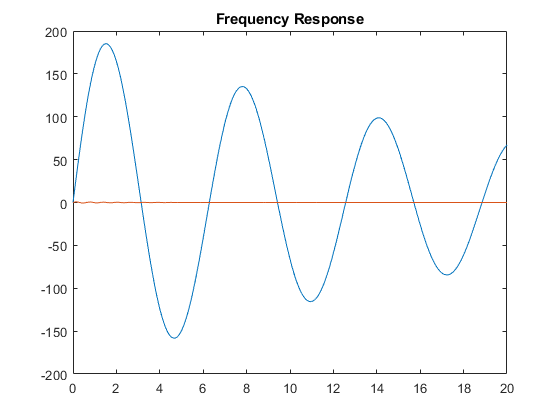

% Create some data for the two curves to be plotted
x  = 0:0.01:20;
y1 = 200*exp(-0.05*x).*sin(x);
y2 = 0.8*exp(-0.5*x).*sin(10*x);
% Create a plot with 2 y axes using the yyaxis function
figure
plot(x, y1)
hold on
plot(x, y2)
hold off
% Add title and x axis label
title('Frequency Response')

Przykład 2. Złe przedstawienie danych

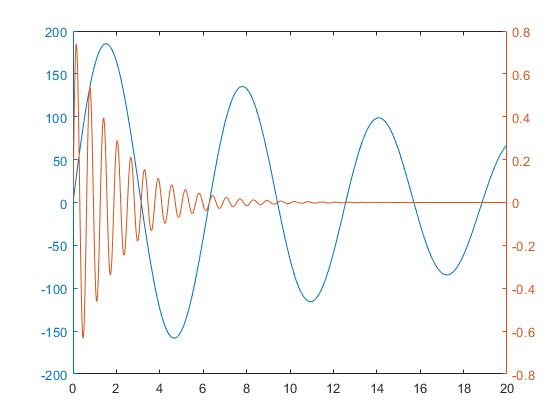

% Create some data for the two curves to be plotted
x  = 0:0.01:20;
y1 = 200*exp(-0.05*x).*sin(x);
y2 = 0.8*exp(-0.5*x).*sin(10*x);
% Create a plot with 2 y axes using the yyaxis function
figure
yyaxis left
plot(x, y1)
yyaxis right
plot(x, y2)

Przykład 3. Dobre przedstawienie danych.

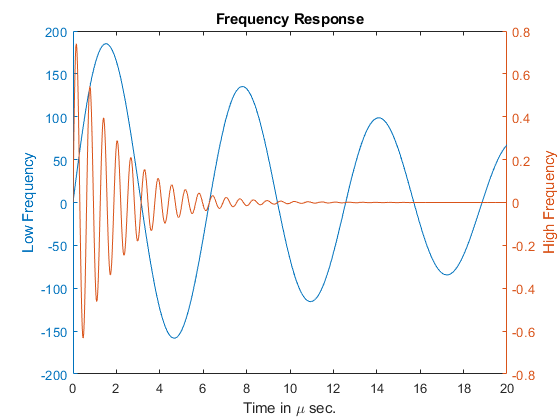

% Create some data for the two curves to be plotted
x  = 0:0.01:20;
y1 = 200*exp(-0.05*x).*sin(x);
y2 = 0.8*exp(-0.5*x).*sin(10*x);
% Create a plot with 2 y axes using the yyaxis function
figure
yyaxis left
plot(x, y1)
ylabel('Low Frequency')
yyaxis right
plot(x, y2)
ylabel('High Frequency')
% Add title and x axis label
xlabel('Time in \mu sec.')
title('Frequency Response')

Zadanie 0a. 

Przedstaw na jednym wykresie funkcję: $x^2 -y^2 =c$ w zależności od parametru $c\in \left\lbrace -4,-2,0,2,4\right\rbrace$. Przedstaw wyniki na jednym wykresie.

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

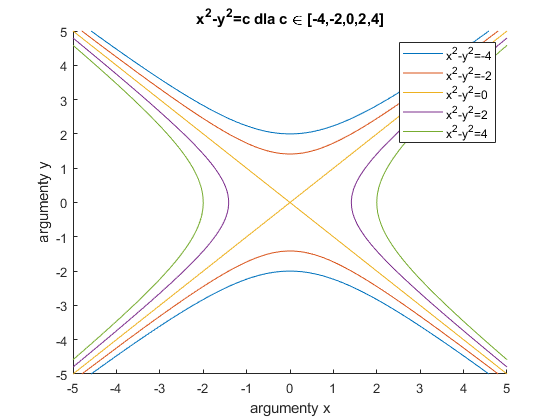

clear all
close all
figure
hold on
for i =[-4, -2, 0, 2, 4]
    fimplicit(@(x,y) x.*x-y.*y-i)
end
title("x^2-y^2=c dla c \in [-4,-2,0,2,4]")
ylabel("argumenty y")
xlabel("argumenty x")
legend("x^2-y^2=-4","x^2-y^2=-2","x^2-y^2=0","x^2-y^2=2","x^2-y^2=4")

"funkcja przedstawia wykresy x^2-y^2=c dla c \in [-4,-2,0,2,4]. Wykres jest w automatycznym przedziale nadanym przez matlaba od -5 do 5 x i y, jest narysowany za pomocą funkcji fimplicit"

ans = "funkcja przedstawia wykresy x^2-y^2=c dla c \in [-4,-2,0,2,4]. Wykres jest w automatycznym przedziale nadanym przez matlaba od -5 do 5 x i y, jest narysowany za pomocą funkcji fimplicit"

Zadanie 0b.

Dane są funkcję: $f\left(x\right)=x^2$ oraz $g\left(x\right)=5+\sin \left(x\right)$

Rozwiąż graficznie równanie: $f\left(x\right)=g\left(x\right)$

Przedstaw w dwóch postaciach:

- użyj legendy do opisu wykresu,

- użyj funkcji text by narzucić tekst na wykres

Nadaj tytuł, podpisz osie (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

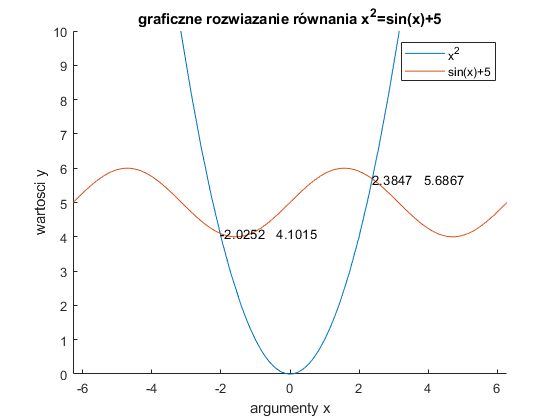

ans = "rozwiązanie wyczytane z wykresu i potwierdzone funkcją vpasolve. wypisane na wykres po konwersji funkcjami duble i num2str, później napisy złączone funkcja join.Zakres osi ustawiony ręcznie na x: [-2*pi, 2*pi] y: [0,10]"

clear all
close all
figure
hold on
fplot(@(x) x.*x)
fplot(@(x) 5+sin(x))
xlim([-2*pi 2*pi])
ylim([0 10])
syms x
x1=vpasolve(x.*x==5+sin(x),x,[-2*pi 0]);
y1=(sin(x1)+5);
text(x1,y1,join([num2str(double(x1))," " ,num2str(double(y1))]))

x2=vpasolve(x.*x==5+sin(x),x,[0 2*pi]);
y2=(sin(x2)+5);
text(x2,y2,join([num2str(double(x2))," " ,num2str(double(y2))]))

title("graficzne rozwiazanie równania x^2=sin(x)+5")
ylabel("wartosci y")
xlabel("argumenty x")
legend("x^2","sin(x)+5")

Wczytywanie pliku:

- load

- xlsread

- readmatrix

- readtable

- readcell

Zadanie 1. 

Wczytaj plik ***temperatury.xlsx ***

Przedstaw dane na wykresie (wykresach) oraz jednym oknie. 

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

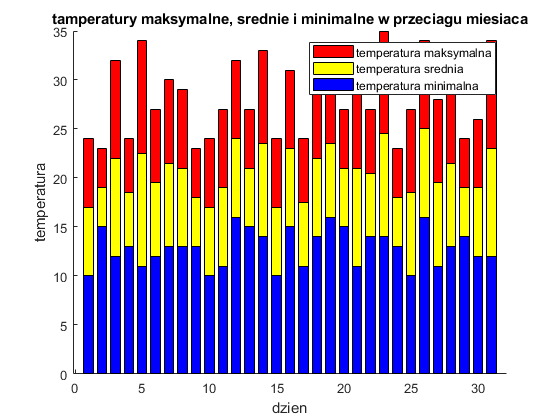

clear all
close all
t=xlsread("temperatury.xlsx");
dzien = t(:,1);
minn = t(:,2);
maxx = t(:,3);
sr = t(:,4);
figure
hold on
bar(dzien,maxx,0.7,'red')
bar(dzien,sr,0.7,'yellow')
bar(dzien,minn,0.7,'blue')
title("tamperatury maksymalne, srednie i minimalne w przeciagu miesiaca")
xlabel("dzien")
ylabel("temperatura")
legend("temperatura maksymalna","temperatura srednia","temperatura minimalna")

Zadanie 2. 

Wczytaj plik ***pogoda.xlsx***

Przedstaw dane na wykresie (wykresach). 

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

clear all
close all
t=xlsread("pogoda.xlsx");
mies=categorical(["styczeń", "luty", "marzec", "kwiecień", "maj", "czerwiec", "lipiec", "sierpień", "wrzesień", "październik", "listopad", "grudzień"]);
mies=reordercats(mies,["styczeń", "luty", "marzec", "kwiecień", "maj", "czerwiec", "lipiec", "sierpień", "wrzesień", "październik", "listopad", "grudzień"]);
figure
hold on
title("opady i temperatura w przeciagu roku")

yyaxis left
bar(mies,t(:,2),"blue")
ylabel("opady (mm)")


yyaxis right
plot(mies,t(:,1),"red")
ylabel("temperatura (C)")

legend("opady","temperatura")


Zadanie 3. 

Załaduj wbudowane dane ***gas.mat***

Przedstaw dane na wykresie (wykresach). 

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

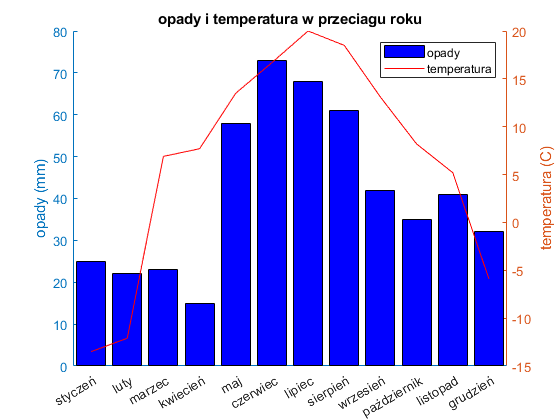

clear all
close all
load gas.mat

figure

ans = "wykres przedstawia zmiany temperatury i ilości opadów w ciągu roku"

hold on
plot(price1)
plot(price2)
title("ceny paliw w stanie Massachusetts w 1993")
xlabel("nr. stacji")
ylabel("cena")
legend("cena na początku miesiąca","cena końcu miesiąca")


Zadanie 4*. 

Załaduj wbudowane dane ***cereal.mat***

Przedstaw wybrane dane na wykresie (wykresach). Nadaj tytuł, podpisz osie, dodaj legendę.

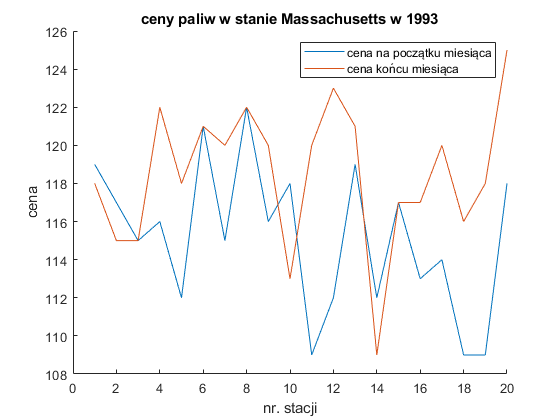

clear all
close all
load cereal.mat
s=size(Name);
tab=[];
for i=1:1:s(1)
    if(Type(i)==0)
        tab=[tab i];

    end

ans = "dane zawarte  w pliku nie zawierają informacji gdzie dokładnie zostaly zebrane te dane, wiec nie da sie dokładnie określić osi x. Wykresy narysowane za pomocą funkcji plot"

end
figure("Name","ingridients of one serving in cereals for cold milk ")
subplot(3,3,1)
bar(Calories(tab))
ylabel("number of calories")
title("calories")
set(gca,'xticklabel',Name(tab))
xtickangle(45)

subplot(3,3,2)
bar(Protein(tab))
ylabel("proteins in g")
title("proteins")
set(gca,'xticklabel',Name(tab))
xtickangle(45)

subplot(3,3,2)
bar(Protein(tab))
ylabel("proteins in g")
title("proteins")
set(gca,'xticklabel',Name(tab))
xtickangle(45)

subplot(3,3,3)
bar(Fat(tab))
ylabel("fat in g")
title("Fat")
set(gca,'xticklabel',Name(tab))
xtickangle(45)

subplot(3,3,4)
bar(Sodium(tab))
ylabel("sodium in mg")
title("Sodium")
set(gca,'xticklabel',Name(tab))
xtickangle(45)

subplot(3,3,5)
bar(Fiber(tab))
ylabel("dietary fiber in g")
title("Dietary fiber")
set(gca,'xticklabel',Name(tab))
xtickangle(45)

subplot(3,3,6)
bar(Carbo(tab))
ylabel("complex carbohydrates in g")
title("Complex carbohydrates")
set(gca,'xticklabel',Name(tab))
ylim([0 inf])                       %pomijam tym dziwny wynik -1 dla Quaker Oatmeal, który chyba symbolizuje brak danej substancji odżywczej
xtickangle(45)

subplot(3,3,7)
bar(Sugars(tab))
ylabel("sugars in g")
title("Sugars")
set(gca,'xticklabel',Name(tab))
ylim([0 inf])                       %ta sam sytuacja co wykres wcześniej
xtickangle(45)

subplot(3,3,8)
bar(Potass(tab))
ylabel("potass in mg")
title("Potassium")
set(gca,'xticklabel',Name(tab))
xtickangle(45)

subplot(3,3,8)
bar(Vitamins(tab))
ylabel("vitamins in % of FDA")
title("Vitamins")
set(gca,'xticklabel',Name(tab))
xtickangle(45)

subplot(3,3,9)
bar(Weight(tab))
ylabel("Weight in oz")
title("Weight of one serving")
set(gca,'xticklabel',Name(tab))
xtickangle(45)

Zadanie 5*. 

Załaduj wbudowane dane ***cities.mat***

Przedstaw wybrane dane na wykresie (wykresach). 

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

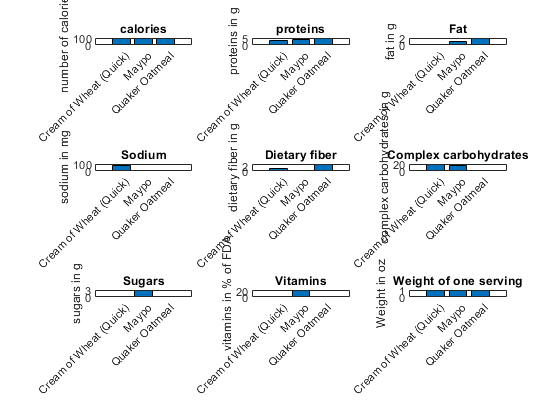

ans = "wykres idealnie porównuje ilości składników odżywczych w poszczególnych rodzajach płatków przeznaconych do spożywania na zimo. Podpis osi x pomijam ponieważ jest oczywisty, a wprowadziłby duży chaos, tak samo jak legenda. Wykres nie jest przeznaczony do oglądania w live editorze, aby był w pełni czytelny, należy otworzyć go w osobnym oknie"

clear all
close all
load cities.mat

state=input("write US state's shortcut which cities you want to compare: ",'s');
s=size(names);
shorts='';
%poniższy algorytm zbiera tablice skrótów stanów z danych nazw.
for i=1:1:s(1)                      
    j=s(2);
    while(double(names(i,j))<double('A') || double(names(i,j))>double('Z'))
        j=j-1;
    end

    sh=names(i,j-1:j);
    if(ismember(sh,shorts)==0)
        shorts=[shorts;sh];
    end
    
    if(double(names(i,j-2))==double('-'))
        sh=names(i,j-4:j-3);
    end
    if(ismember(sh,shorts)==0)
        shorts=[shorts;sh];
    end
end

%Algorytm sprawdzający czy skrót jest w danym zestawie.
if (ismember(state,shorts)==1)
    tab=[];
    %poniższy algorytm zbiera do tablicy tab wszystkie stany spełniające kryteria
    for i=1:1:s(1)
        j=s(2);
        while(double(names(i,j))<double('A') || double(names(i,j))>double('Z'))
            j=j-1;
        end
        if(names(i,j-1:j)==state | names(i,j-4:j-3)==state)
            tab=[tab i];
        end
    end
    t2=size(tab);
    t2=1:1:t2(2);
    t1=ratings(tab,:);
    
    figure("Name",join(["Comparison of" state "cities on various fields"]))
    
    for j=1:1:9
        subplot(3,3,j)
        bar(t1(:,j))
        ylabel(join(["Quality of " categories(j,:)]))
        title(categories(j,:))
        xticks(t2)
        xticklabels(names(tab,:))
        xtickangle(45)
    end
else
    "There is no state with this shortcut in this set of data"
end

Zadanie 6. 

Załaduj wbudowane dane*** FisherIris.mat***

Podziel dane *mean* według gatunku 

((1,50)->setosa, 

(51,100)-> virginica, 

(101,151)-> versicolor)

Policz średnią i odchylenie dla każdej kolumny, utwórz errorbar. 

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

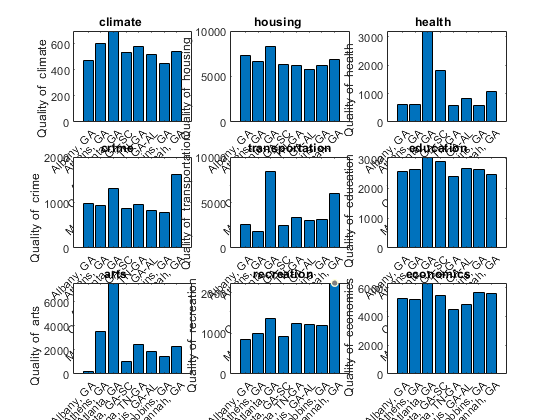

ans = "Porównanie zrobione podobną metodą co poprzednie zadanie, z ulepszeniem w postaci pętli for która rusyje wykresy i możliwoscią wybrania stanu"

clear all

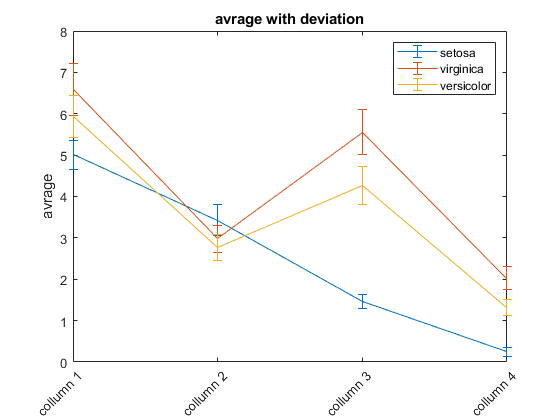

close all
load FisherIris.mat

sr=[0 0 0 0; 0 0 0 0; 0 0 0 0];
dev=[0 0 0 0; 0 0 0 0; 0 0 0 0];
setosanum=0;
virginicanum=0;
versicolornum=0;
s=size(species);
for i=1:1:s(1)
    if strcmp(species(i),'setosa')
        for j=1:1:4
            sr(1,j)=meas(i,j)+sr(1,j);
        end
        setosanum=setosanum+1;
    elseif strcmp(species(i),'virginica')
        for j=1:1:4
            sr(2,j)=meas(i,j)+sr(2,j);
        end
        virginicanum=virginicanum+1;
    elseif strcmp(species(i),'versicolor')
        for j=1:1:4
            sr(3,j)=meas(i,j)+sr(3,j);
        end
        versicolornum=versicolornum+1;
    end
end

for j=1:1:4
    sr(1,j)=sr(1,j)./setosanum;
end
for j=1:1:4
    sr(2,j)=sr(2,j)./virginicanum;
end
for j=1:1:4
    sr(3,j)=sr(3,j)./versicolornum;
end


for i=1:1:s(1)
    if strcmp(species(i),'setosa')
        for j=1:1:4
            dev(1,j)=((meas(i,j)-sr(1,j)).^2)+dev(1,j);
        end
    elseif strcmp(species(i),'virginica')
        for j=1:1:4
            dev(2,j)=((meas(i,j)-sr(2,j)).^2)+dev(2,j);
        end
    elseif strcmp(species(i),'versicolor')
        for j=1:1:4
            dev(3,j)=((meas(i,j)-sr(3,j)).^2)+dev(3,j);
        end
    end
end

dev(1,:)=dev(1,:)/setosanum;
dev(2,:)=dev(2,:)/virginicanum;
dev(3,:)=dev(3,:)/versicolornum;
dev=dev.^(1/2);


figure("Name", "Avrage of fisher's 1936 iris data")
errorbar(transpose(sr),transpose(dev))
ylabel("avrage")
title("avrage with deviation")
xticks([1,2,3,4])
xticklabels(["collumn 1","collumn 2","collumn 3","collumn 4"])
xtickangle(45)
legend('setosa', 'virginica', 'versicolor')

figure
gscatter(meas(:,1),meas(:,2),species)
xlabel("collumn 1")
ylabel("collumn 2")
title("Iris scatter graph")

"najpierw sumuje poszczegolne kolumny dla poszczegolnych gatunkow, uzalezniając to od faktycznego gatunku, poniważ polecenie podaje te gatunki w złej kolejności. " + ...
    "Następnie dzielę tą sumę przez ilość ryb w poszczególnych gatunkach. " + ...
    "Następnie na podstawie pętli liczących sumę tworzę pętle liczące odchylenie. " + ...

    "Na sam koniec wystarczy każdą wartość w tabeli dev zawierającej odchylenia podzelić przez ilość poszczególnych ryb i spierwiastkować. " + ...
    "Następnie tworzę wykres funkcją errorbar przedstawiający zależności między średnimi poszczególnych kolumn dla poszczególnych ras i " + ...
    "wykres typu gscatter przedstawiający zależności między 1 i 2 kolumną dla poszczególnych ras"

Zadanie 7*. 

Załaduj wbudowane dane ***spine X***

Przedstaw dane X na wykresach różnych wykresach (plot, hist,mesh). Spróbuj na podstawie wykresów zgadnąć co to za dane.

Na końcu użyj funkcji imagesc(X).

Dopisz wnioski i spostrzeżenia.

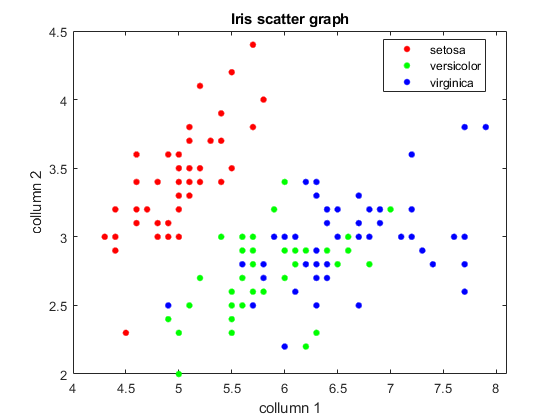

clear all
close all
load spine X

ans = "najpierw sumuje poszczegolne kolumny dla poszczegolnych gatunkow, uzalezniając to od faktycznego gatunku, poniważ polecenie podaje te gatunki w złej kolejności. Następnie dzielę tą sumę przez ilość ryb w poszczególnych gatunkach. Następnie na podstawie pętli liczących sumę tworzę pętle liczące odchylenie. Na sam koniec wystarczy każdą wartość w tabeli dev zawierającej odchylenia podzelić przez ilość poszczególnych ryb i spierwiastkować. Następnie tworzę wykres funkcją errorbar przedstawiający zależności między średnimi poszczególnych kolumn dla poszczególnych ras i wykres typu gscatter przedstawiający zależności między 1 i 2 kolumną dla poszczególnych ras"

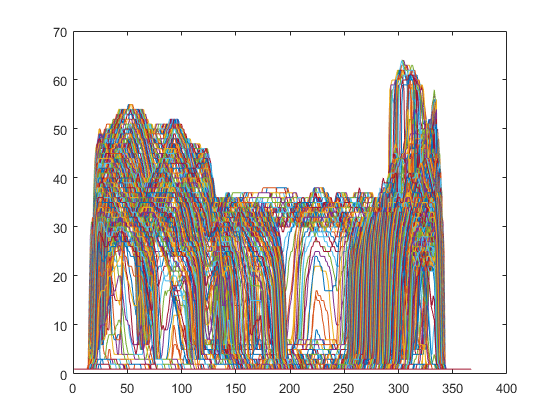

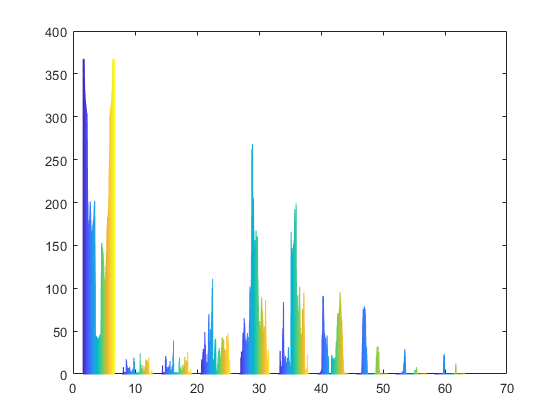

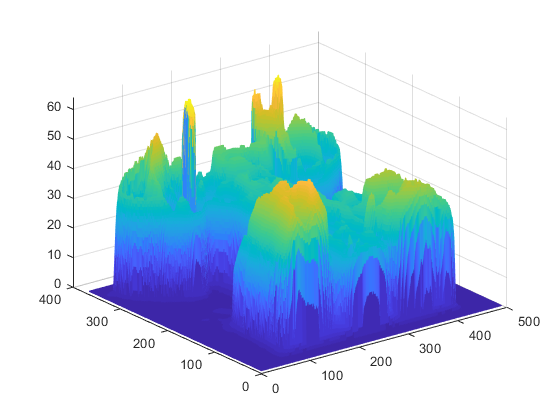

ans = "wykres typu plot i mesh wskazywałby na mapę hipsometryczną jakiejś katedry, wg mnie bardzo przypomina to katedrę Notre Dame, natomiast histogram nie mówi nic"

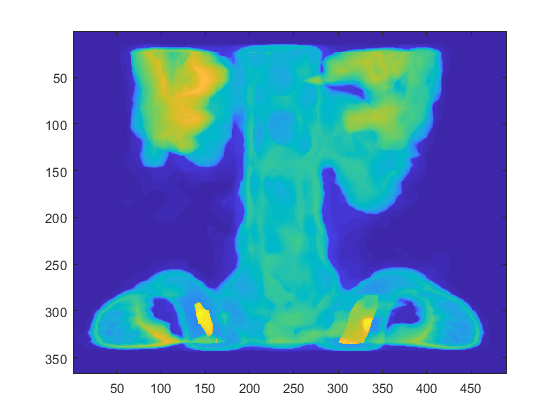

ans = "natomiast wykres imagesc przypomina rentgena płuc, kręgosłupa i miednicy. Nazwa danych wydawałaby się potwierdzać tą teorię"

figure
plot(X)
figure
hist(X)
figure
mesh(X)
imagesc(X)